data = readtable("data/Perhaps/Wind-Turbine-SCADA-signals-2017_0 (1).xlsx")

data = 209236×83 table
    Turbine_ID              Timestamp              Gen_RPM_Max    Gen_RPM_Min    Gen_RPM_Avg    Gen_RPM_Std    Gen_Bear_Temp_Avg    Gen_Phase1_Temp_Avg    Gen_Phase2_Temp_Avg    Gen_Phase3_Temp_Avg    Hyd_Oil_Temp_Avg    Gear_Oil_Temp_Avg    Gear_Bear_Temp_Avg    Nac_Temp_Avg    Rtr_RPM_Max    Rtr_RPM_Min    Rtr_RPM_Avg    Amb_WindSpeed_Max      Amb_WindSpeed_Min       Amb_WindSpeed_Avg       Amb_WindSpeed_Std       Amb_WindDir_Relative_Avg    Amb_WindDir_Abs_Avg    Amb_Temp_Avg    Prod_LatestAvg_ActPwrGen0    Prod_LatestAvg_ActPwrGen1

data = data{:,:}

Unable to concatenate the table variables 'Turbine_ID' and 'Gen_Phase1_Temp_Avg', because their types are cell and double.

% 2017-10-17T08:38:00+00:00
ix2 = data.Turbine_ID == "T06" & data.Timestamp < "2017-10-18T00:00:00+00:00" & data.Timestamp > "2017-09-17T00:00:00+00:00";
test = data(ix2, :);
test = sortrows(test, "Timestamp")

test = 4463×83 table
    Turbine_ID              Timestamp              Gen_RPM_Max    Gen_RPM_Min    Gen_RPM_Avg    Gen_RPM_Std    Gen_Bear_Temp_Avg    Gen_Phase1_Temp_Avg    Gen_Phase2_Temp_Avg    Gen_Phase3_Temp_Avg    Hyd_Oil_Temp_Avg    Gear_Oil_Temp_Avg    Gear_Bear_Temp_Avg    Nac_Temp_Avg    Rtr_RPM_Max    Rtr_RPM_Min    Rtr_RPM_Avg      Amb_WindSpeed_Max         Amb_WindSpeed_Min         Amb_WindSpeed_Avg          Amb_WindSpeed_Std       Amb_WindDir_Relative_Avg    Amb_WindDir_Abs_Avg    Amb_Temp_Avg    Prod_LatestAvg_ActPwrGen0    Prod_LatestAvg_ActPw

find(test.Timestamp > "2017-10-17T08:38:00+00:00")

ans =         4372
        4373
        4374
        4375
        4376
        4377
        4378
        4379
        4380
        4381


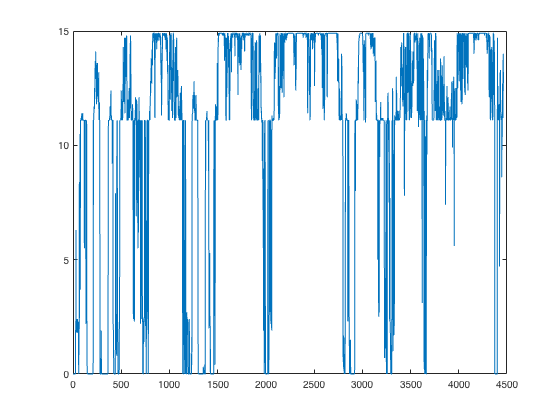

plot(str2double(test.Rtr_RPM_Avg))